# **Hand to Eye Calibration**

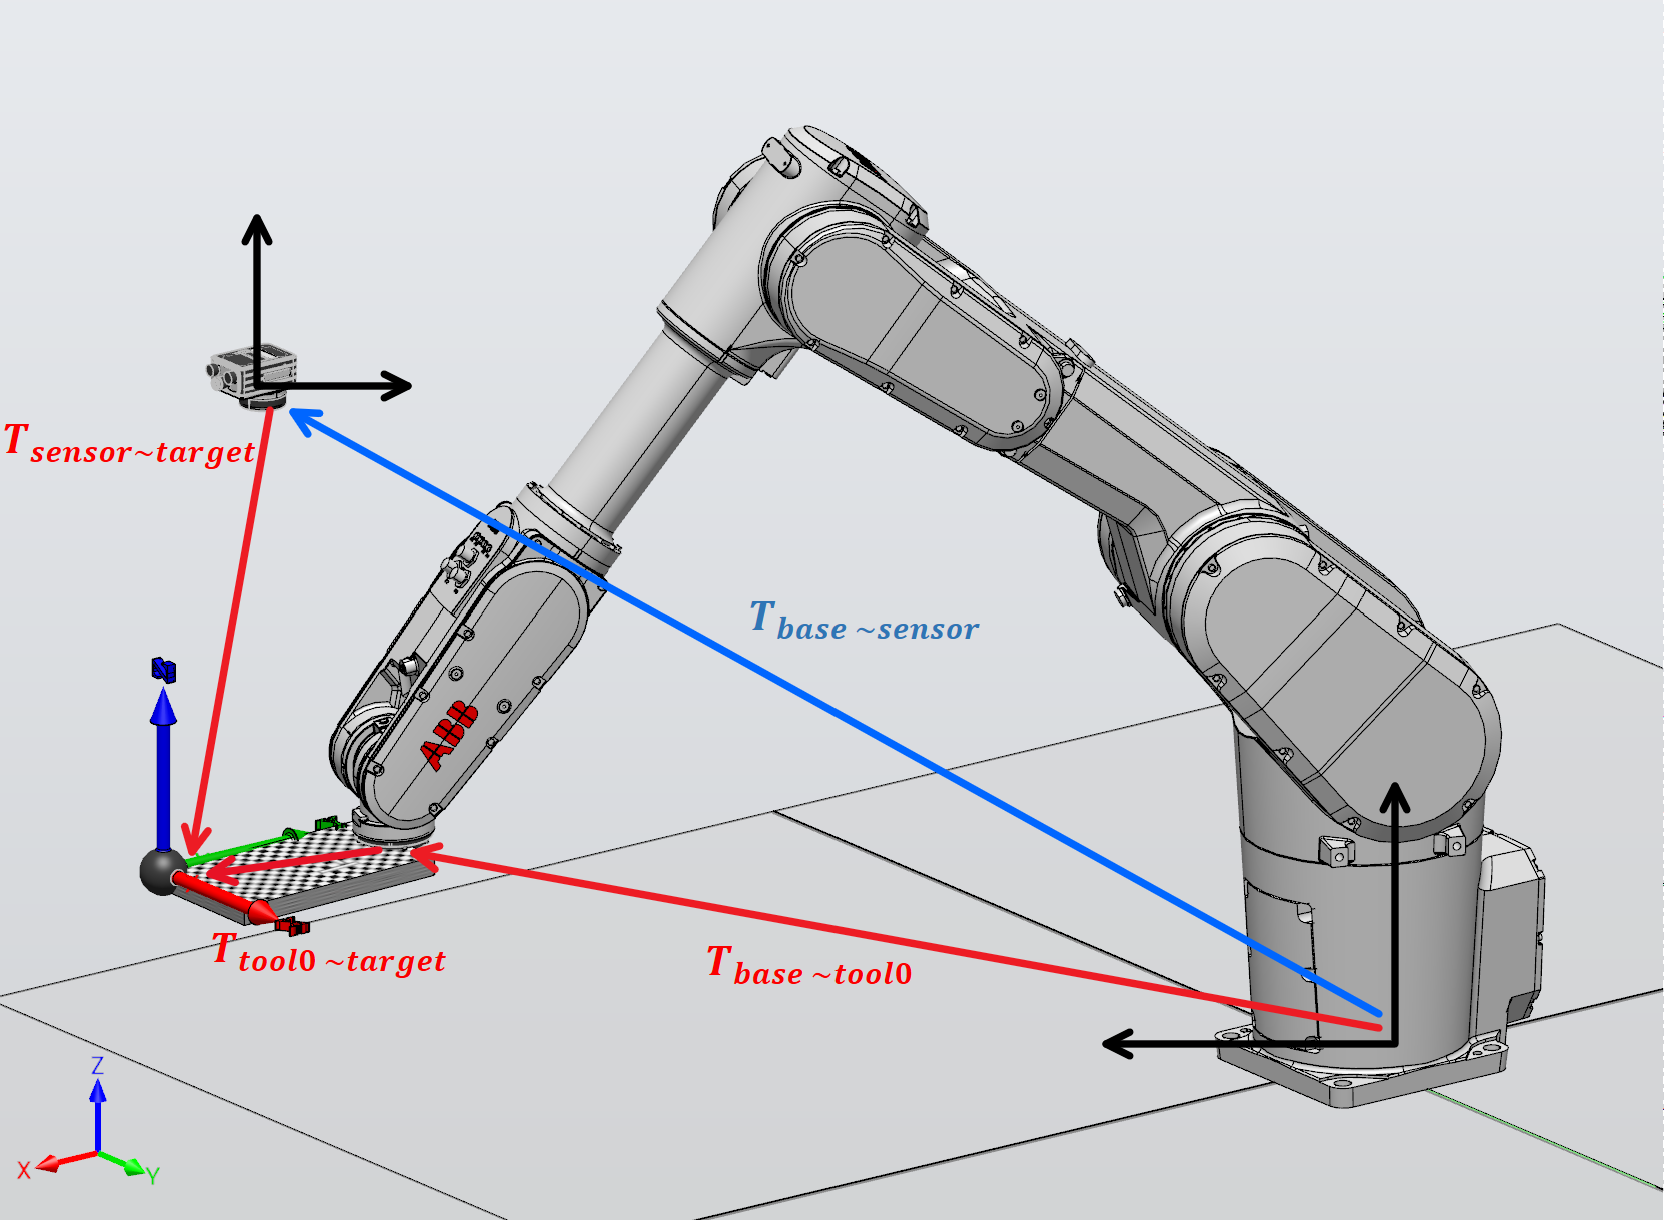

#### **Create Simulation Data**

clc;clear;close all
[filepath,~,~] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(filepath);
addpath(fullfile(filepath,'myfunc'),'-begin')

[T_r, T_s, X_ref] = DataEye2Hand(10,[2/180*pi,1/1000]);

#### Calibration (AX = XB)

X_calc = EyeToHand(T_r,T_s)

X_calc =     0.9971   -0.0648    0.0410    1.2632
    0.0672    0.9961   -0.0579   -1.7955
   -0.0370    0.0605    0.9975   -1.1961
         0         0         0    1.0000


#### Check Error

fprintf('Error Compare with Ref: %.4f , %.4f',diffSE3(X_ref,X_calc,'self'))

Error Compare with Ref: 0.0070 , 0.0031

[err,str] = EyeToHandError(T_r,X_calc,T_s);
for i = 1:length(str)
    fprintf('%s\n',str{i});
end

Calibration Error

10 Measurements

Avg Tran / Rot:  5.90 mm /  1.82 deg
Max Tran / Rot:  8.37 mm /  3.12 deg
Std Tran / Rot:  1.77 mm /  1.05 deg


#### **Plot tool Flange ~ Target**

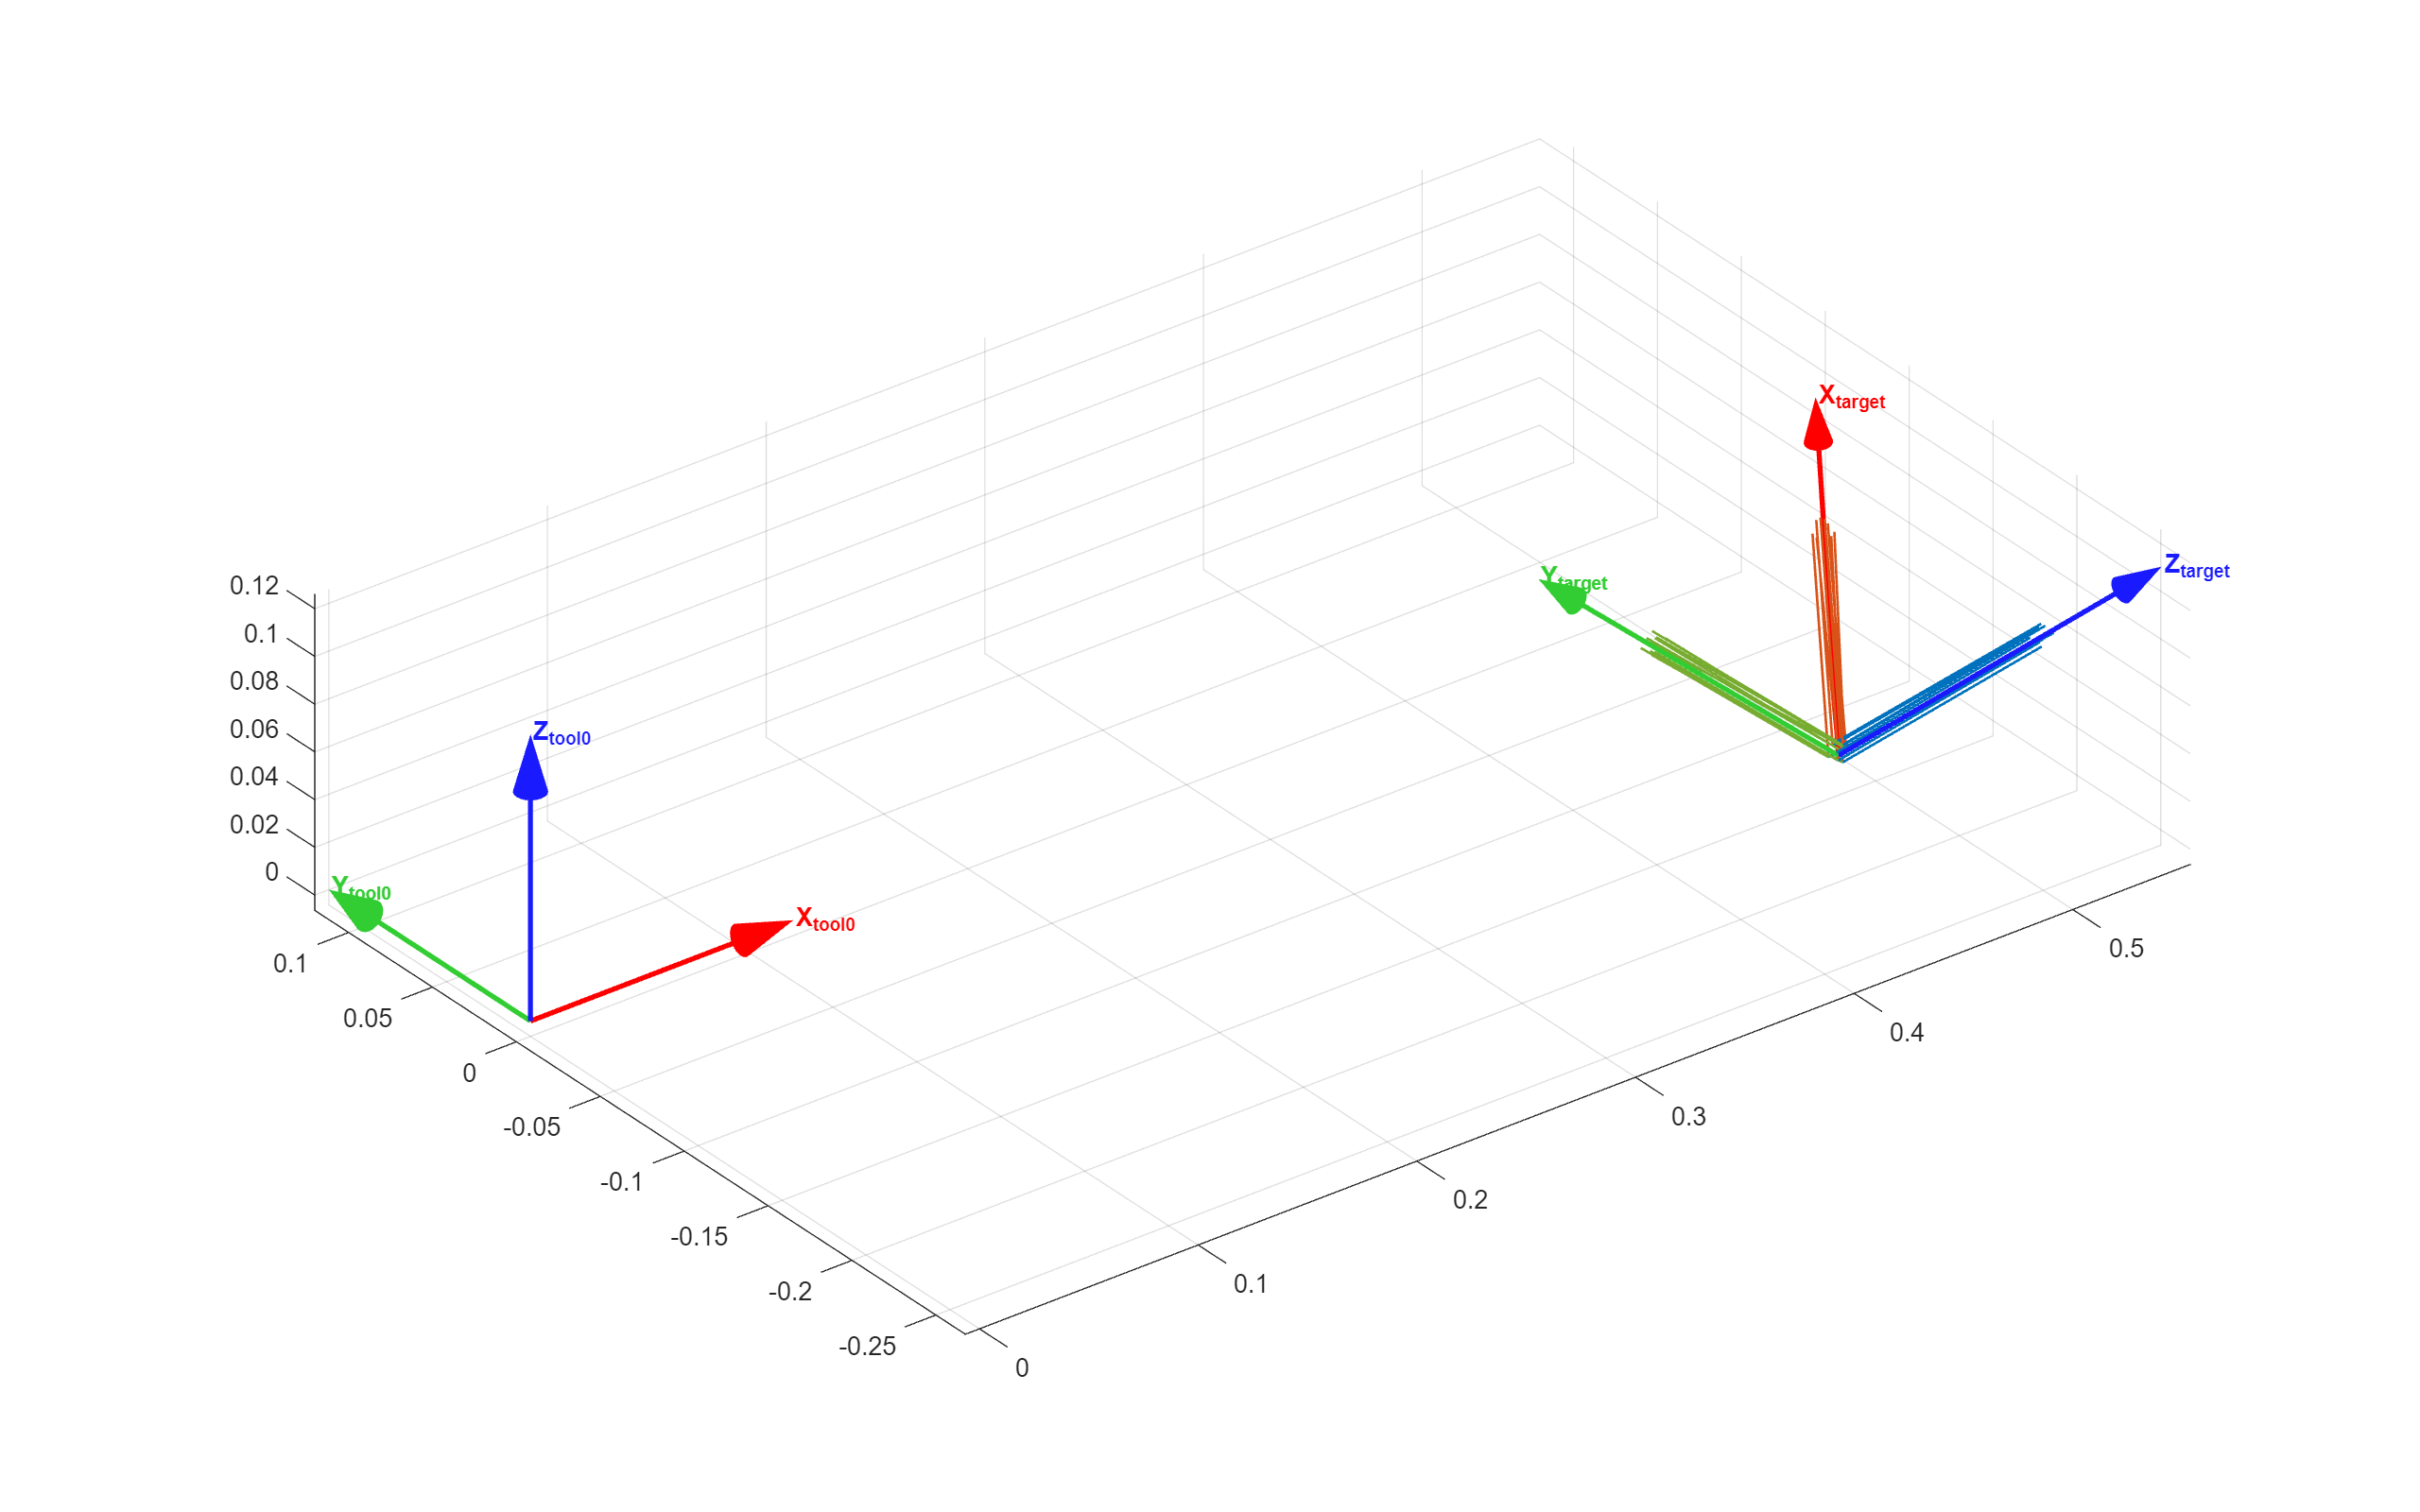

tooldata = pagemtimes(pagemtimes(HomInv(T_r),X_calc),T_s);
ref_tool = HomInv(T_r(:,:,1))*X_ref*T_s(:,:,1);
scale = mean(sum(tooldata(1:3,4,:).^2).^0.5,'all')/5;

f = figure;
for i = 1:size(tooldata,3)
    PlotFrame(tooldata(:,:,i),'scale',scale,'linewidth',1,'style','-',...
    'colorind',2,'text','off');hold on
end
PlotFrame(eye(4),'scale',scale*1.2,'linewidth',2,'style','-',...
    'arrowsize',1/5,'colorind',1,'text','on','frameind','_{tool0}');hold on
PlotFrame(ref_tool,'scale',scale*1.6,'linewidth',2,'style','-',...
    'arrowsize',1/8,'colorind',1,'text','on','frameind','_{target}');hold on
grid on; axis equal;
set(f,'Units','normalized','Position',[0,0,1,1])